clear;
load('data1.mat');
dataval = table(Xval(:,1),Xval(:,2),yval==1,'VariableNames',{'Throughput','Latency','Anomaly'});
summary(dataval)

Variables:

    Throughput: 307×1 double

        Values:

            Min       0.30794 
            Median     14.031 
            Max        28.542 

    Latency: 307×1 double

        Values:

            Min        5.3914 
            Median     15.021 
            Max        23.356 

    Anomaly: 307×1 logical

        Values:

            True         9   
            False      298   



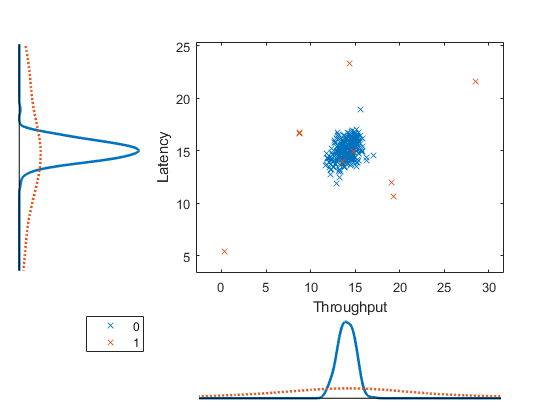


scatterhist(dataval.Throughput,dataval.Latency,'Group',dataval.Anomaly,'Kernel','on','Marker','x')
xlabel('Throughput');
ylabel('Latency');

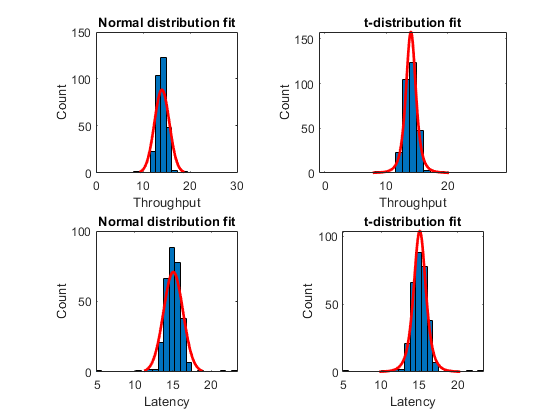


f = figure;
subplot(2,2,1);
histfit(dataval.Throughput,25,'normal');
title('Normal distribution fit')
xlabel('Throughput');
axis square
subplot(2,2,2); 
histfit(dataval.Throughput,25,'tlocationscale');
title('t-distribution fit')
xlabel('Throughput');
subplot(2,2,3);
histfit(dataval.Latency,25,'normal');
title('Normal distribution fit')
xlabel('Latency');
axis square
subplot(2,2,4); 
histfit(dataval.Latency,25,'tlocationscale');
title('t-distribution fit')
xlabel('Latency');
set([f.Children.YLabel],'String','Count')
axis square



mu = zeros(1,2);
sigma = mu;
distMdl1 = fitdist(dataval.Throughput,'Normal')

distMdl1 =   NormalDistribution

  Normal distribution
       mu = 14.0193   [13.8408, 14.1978]
    sigma = 1.58937   [1.47281, 1.72612]


mu(1) = distMdl1.mu;
sigma(1) = distMdl1.sigma;


%Fit a probability distribution to data using the Distribution Fitter App
%instructions for fitting a normal distribution to the latency data using the Distribution Fitter App and export/extract the model parameters:
%In the 'Apps' tab,  expand the list of apps and select 'Distribution Fitter' from the 'Math, Statistics, and Optimization' group.
%Click on the 'Data' button.
%Expand the 'Data' drop-down menu under 'Import workspace vectors' and select 'Xval'.
%Click on the 'Select Column or Row' button. In the box that appears, click on the '2' at the top of the second column to select the entire column, then click 'OK'.
%Click on the 'Create Data Set' button, then click 'Close'.

%Fit a normal distribution and export the NormalDistribution variable to the workspace
%In the Distribution Fitter window, click on the ''New Fit' button
%In the 'New Fit' window, confirm that the second column of Xval is selected in 'Data', and 'Normal' is selected in 'Distribution'.
%Click the 'Apply' button.
%Click on the 'Save to Workspace' button. 
%In the 'Save fitted distribution as:' box that appears, enter 'distMdl2' then click 'Ok'
%Close the 'Edit Fit' menu (the 'New Fit' menu becomes the 'Edit Fit' menu once a distribution is fitted).

mu(2) = distMdl2.mu;

Unable to resolve the name distMdl2.mu.

sigma(2) = distMdl2.sigma;

probContour(dataval,mu,sigma);

epsilon = 1e-4;
% Compute the probability contours
Xvalprobs = mvnpdf(Xval,mu,sigma.^2);
yvalpred = Xvalprobs < epsilon;
confmat = confusionmat(yvalpred,dataval.Anomaly)
precision = confmat(2,2)/(confmat(2,2)+confmat(1,2));
recall = confmat(2,2)/(confmat(2,2)+confmat(2,1)); 
F1 = 2*precision*recall/(precision+recall);
fprintf('Epsilon: %g | Precision: %g | Recall: %g | F1: %g',epsilon, precision,recall,F1);
% Probability contour plot
[Xplot,Yplot,Zplot] = probContour(dataval,mu,sigma); hold on;
contour(Xplot,Yplot,Zplot,[epsilon epsilon],'r');
errinds = yvalpred ~= yval;
plot(dataval.Throughput(errinds),dataval.Latency(errinds),'mo','MarkerSize',10); 
hold off;
legend({'Probability contours','Normal behavior','Anomalous behavior','Cuttoff contour',...
        'Misclassified points'},'Location','northeast');  
    

[Xroc,Yroc,T,auc,Opt] = perfcurve(yval,Xvalprobs,0);
Topt = T(Opt(1) == Xroc & Opt(2) == Yroc);
fprintf('Best epsilon found using ROC performance curve: %g',Topt)
plot(Xroc,Yroc); hold on;
plot(Opt(1),Opt(2),'ro'); 
hold off; axis square;
xlabel('False positive rate (1-specificity)');
ylabel('True positive rate (sensitivity)');
title('ROC curve')


% Replot existing ROC curve
plot(Xroc,Yroc,'b'); hold on;
plot(Opt(1),Opt(2),'bo'); 
xlabel('False positive rate (1-specificity)');
ylabel('True positive rate (sensitivity)');
title('ROC curve');

% Compute and plot the full covariance model ROC curve
Xvalprobs2 = mvnpdf(Xval,mu,cov(Xval));
[Xroc2,Yroc2,T2,auc2,Opt2] = perfcurve(yval,Xvalprobs2,0);
Topt2 = T2(Opt2(1) == Xroc2 & Opt2(2) == Yroc2);
fprintf('Best epsilon for full covariance model found: %g',Topt2)
plot(Xroc2,Yroc2,'r');
plot(Opt2(1),Opt2(2),'rx'); hold off;
legend({'Independent','Optimal Point','Full','Optimal Point'}, 'Location','NorthEast')
fprintf('Independent variable AUC: %g | Full covariance AUC: %g', auc,auc2);